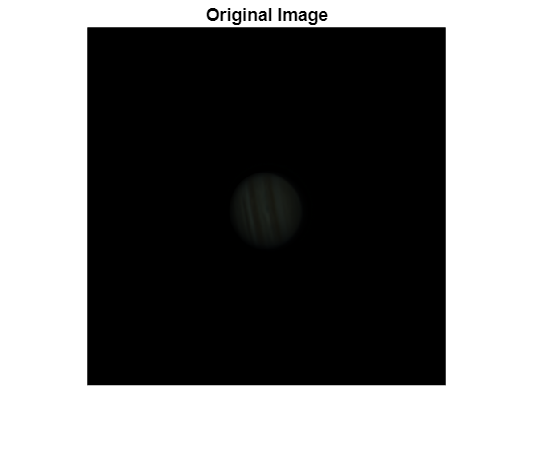

% Read the image
image = imread("D:\Space\Sahil\pipp_20241004_191434\AS_P50\04_08_27_lapl4_ap41_conv.tif");
image = im2double(image); % Convert to double for processing
figure, imshow(image), title('Original Image');

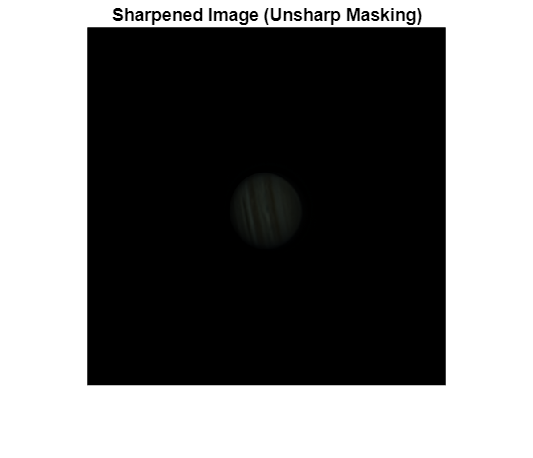

% Unsharp Masking
sharpImage = imsharpen(image, 'Radius', 2, 'Amount', 1);
figure, imshow(sharpImage), title('Sharpened Image (Unsharp Masking)');

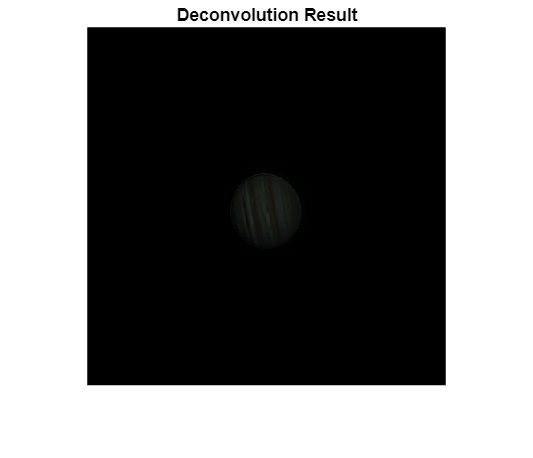

% Simulate a point spread function (PSF) and apply deconvolution
PSF = fspecial('gaussian', 5, 1); % Adjust parameters based on blur level
deconvImage = deconvlucy(sharpImage, PSF, 10); % Perform deconvolution
figure, imshow(deconvImage), title('Deconvolution Result');

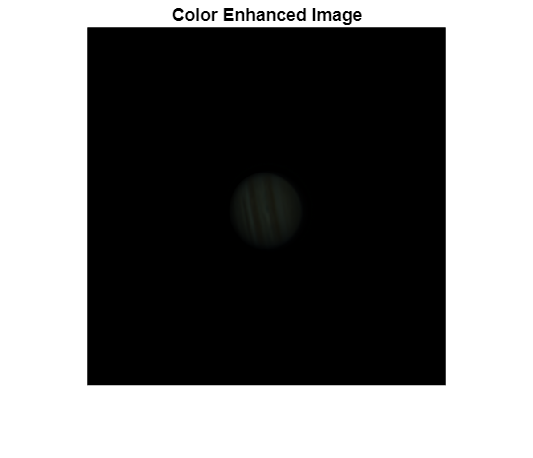

% Adjust color balance and saturation
hsvImage = rgb2hsv(image);
hsvImage(:, :, 2) = hsvImage(:, :, 2) * 1.2; % Increase saturation
enhancedColorImage = hsv2rgb(hsvImage);
figure, imshow(enhancedColorImage), title('Color Enhanced Image');